clear;
noise_type_str = ["NO NOISE", "BIT FLIP", "DEPOLARIZING", "DEPHASING", "AMPLITUDE DAMPING"];


noise_p=0.001;
lambda=2;
offset=2;
dt=0.005;
nqubits=9;
init_cond=1;

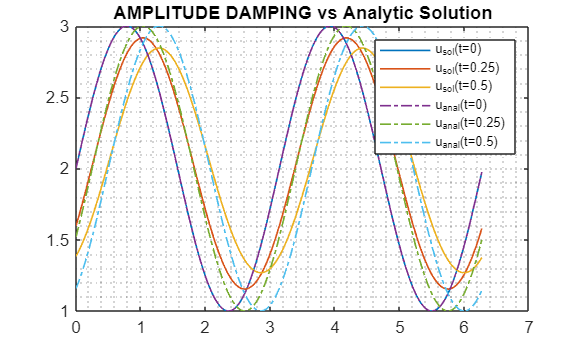

noise_types_list = [4];

for noise_type=noise_types_list
    name = strcat(noise_type_str(noise_type+1), num2str(noise_p),...
        '_lambda',num2str(lambda),...
        '_offset',num2str(offset),...
        '_dt', num2str(dt),...
        '_nqubits',num2str(nqubits),...
        '_initCond',num2str(init_cond));
    load(strcat('DATA/MAT_',name,'.mat'));
    fig_comparison = figure(Position=[0,0,640,384]);
    % plot 3 lines
    nlines=3;
    step=floor((length(t)-1)/(nlines-1));
    hold on;
    for it = 1:step:length(t)
        plot(x,u(it,:),'LineWidth',1, 'DisplayName',strcat('u_{sol}(t=',num2str(dt*(it-1)),')'));
    end
    for it = 1:step:length(t)
        plot(x,u_anal(it,:),'-.','LineWidth',1, 'DisplayName',strcat('u_{anal}(t=',num2str(dt*(it-1)),')'));
    end
    hold off;
    legend(FontSize=8);
    box on;
    grid minor;
    title(strcat(noise_type_str(noise_type+1), ' vs Analytic Solution'));
    
    savefig(fig_comparison, strcat('FIG/SingleWv_', name,'.fig'))
    exportgraphics(fig_comparison, strcat('FIG/SingleWv_', name,'.pdf'));
end